lambda_pla = 0.13;
lambda_luft = 25.50 * 10^-3;
M_vand = 997;
c_vand = 4187;

l_pla = 5 * 10^-3;
l_luft = 10 * 10^-3;
H_tank = 0.1;
B_tank = 0.1;
L_tank = 0.1;
T_luft = 21;

V_tank = H_tank * B_tank * L_tank;
A_tank = H_tank * B_tank * 2 + B_tank * L_tank * 2 + L_tank * H_tank * 2;

U_pla = lambda_pla / l_pla;
U_luft = lambda_luft / l_luft;
U_tot = 1/((1/U_pla)+(1/U_luft)+(1/U_pla));

m_dej = V_tank * M_vand;
Q_dej = c_vand * m_dej;
T_dej = T_luft, zeros(1, 10799);

T_dej = 21

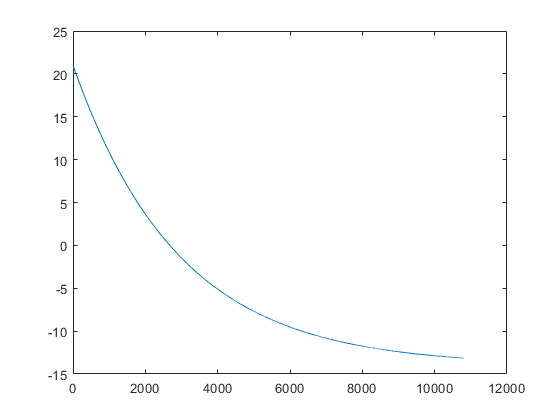


for s = 2:10800
    phi_tab = U_tot * A_tank * (T_luft - T_dej(s-1));
    phi_peltier = 50 - 1.3*(T_luft - T_dej (s-1));
    phi_tot = phi_peltier - phi_tab;
    T_dej(s) = T_dej(s-1) - phi_tot / Q_dej;
end
%%
plot(T_dej);